%AB-CDEFG-H
%20-42406-1
%A1=GD;A2=AF
A1=62

A1 = 62

A2=20

A2 = 20

C=4

C = 4

F=0

F = 0

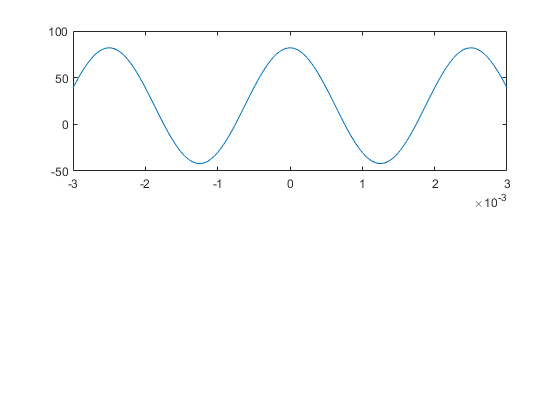

fs=30e3;
dur=0.003;
t=-dur:1/fs:dur;
x1=A1*cos(2*pi*C*100*t);
x2=A2*cos(2*pi*F*100*t);
x3=x1+x2;
xlabel('Time(s)');
ylabel('Amplitude');
plot(t,x3);

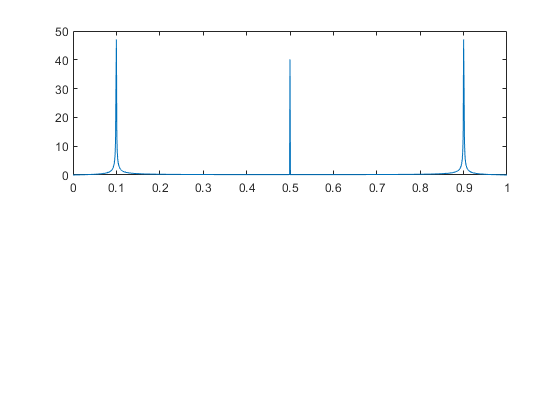

fs=1000;
t=0:1/fs:1;
x1=A1*cos(2*pi*C*100*t);
x2=A2*cos(2*pi*F*100*t);
x3=x1+x2;
x=fft(x3);
fx3=fftshift(x)/(fs/2);
f=0:1/fs:1;
plot(f,abs(fx3));

bandwith=obw(x,fs);

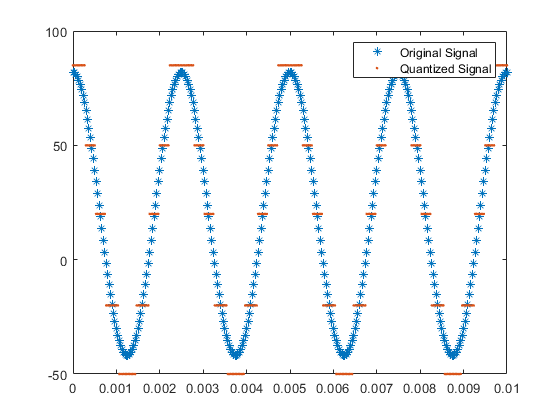

%Pakage load Communication
fs=30e3;
t=0:1/fs:0.01;
x1=A1*cos(2*pi*C*100*t);
x2=A2*cos(2*pi*F*100*t);
x3=x1+x2;
f=6;
partition=[-65.5,-35,0,35,65.5];
codebook=[-85,-50,-20,20,50,85];
[index,quants]=quantiz(x3,partition,codebook);
plot(t,x3,'*',t,quants,'.');
legend('Original Signal','Quantized Signal')